clear
clf

% from experiment 1 %
beta = 162.4044

beta = 162.4044

Ut = 0.0263

Ut = 0.0263

Is = 6.1754 * (10^-15)

Is = 6.1754e-15


load('100kohm/Vin.mat')
load('100kohm/Iout_ch2.mat')
load('100kohm/Iout_ch1.mat')
Vin_100k = Vin;
Ib_100k = Iout_ch1;
Ie_100k = -Iout_ch2;
Ic_100k = Ie_100k - Ib_100k;
[first_resistor_100k, last_resitor_100k, mmax_resistor_100k, bmax_resistor_100k, Nmax_resistor_100k]=linefit(Vin_100k(200:end), Ic_100k(200:end), 5e-4)

first_resistor_100k = 91

last_resitor_100k = 112

mmax_resistor_100k = 1.0058e-05

bmax_resistor_100k = -5.4089e-06

Nmax_resistor_100k = 22

R_100k = 1/mmax_resistor_100k

R_100k = 9.9420e+04

Rb_100k = diff(Vin_100k)./diff(Ib_100k);
Rb_theoretical_100k = (Ut./Ib_100k) + ((beta + 1).*R_100k);
Gm_100k = diff(Ic_100k)./diff(Vin_100k);
Gm_theoretical_100k = Ic_100k ./ ((R_100k.*Ie_100k)+ Ut);
Ir_theoretical_100k = (Vin_100k * mmax_resistor_100k) + bmax_resistor_100k;

load('10kohm/Vin.mat')
load('10kohm/Iout_ch2.mat')
load('10kohm/Iout_ch1.mat')
Vin_10k = Vin;
Ib_10k = Iout_ch1;
Ie_10k = -Iout_ch2;
Ic_10k = Ie_10k - Ib_10k;
[first_resistor_10k, last_resitor_10k, mmax_resistor_10k, bmax_resistor_10k, Nmax_resistor_10k]=linefit(Vin_10k(200:end), Ic_10k(200:end), 5e-4)

first_resistor_10k = 209

last_resitor_10k = 251

mmax_resistor_10k = 1.0065e-04

bmax_resistor_10k = -6.1696e-05

Nmax_resistor_10k = 43

R_10k = 1/mmax_resistor_10k

R_10k = 9.9357e+03

Rb_10k = diff(Vin_10k)./diff(Ib_10k);
Rb_theoretical_10k = (Ut./Ib_10k) + ((beta + 1).*R_10k);
Gm_10k = diff(Ic_10k)./diff(Vin_10k);
Gm_theoretical_10k = Ic_10k ./ ((R_10k.*Ie_10k)+ Ut);
Ir_theoretical_10k = (Vin_10k * mmax_resistor_10k) + bmax_resistor_10k;

load('1kohm/Vin.mat')
load('1kohm/Iout_ch2.mat')
load('1kohm/Iout_ch1.mat')
Vin_1k = Vin;
Ib_1k = Iout_ch1;
Ie_1k = -Iout_ch2;
Ic_1k = Ie_1k - Ib_1k;
[first_resistor_1k, last_resitor_1k, mmax_resistor_1k, bmax_resistor_1k, Nmax_resistor_1k]=linefit(Vin_1k, Ic_1k, 5e-4)

first_resistor_1k = 125

last_resitor_1k = 501

mmax_resistor_1k = 0.0010

bmax_resistor_1k = -6.8324e-04

Nmax_resistor_1k = 377

R_1k = 1/mmax_resistor_1k

R_1k = 997.1706

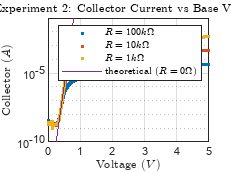

Rb_1k = diff(Vin_1k)./diff(Ib_1k);
Rb_theoretical_1k = (Ut./Ib_1k) + ((beta + 1).*R_1k);
Gm_1k = diff(Ic_1k)./diff(Vin_1k);
Gm_theoretical_1k = Ic_1k ./ ((R_1k.*Ie_1k)+ Ut);
Ir_theoretical_1k = (Vin_1k * mmax_resistor_1k) + bmax_resistor_1k;

semilogy(Vin_100k, Ic_100k, '.');
hold on;
semilogy(Vin_10k, Ic_10k, '.');
semilogy(Vin_1k, Ic_1k, '.');
semilogy(Vin_1k, Is.*exp(Vin_1k./Ut))

title("Experiment 2: Collector Current vs Base Voltage", "Interpreter", "latex");
xlabel("Voltage ($V$)", "Interpreter", "latex");
ylabel("Collector ($A$)", "Interpreter", "latex");
ylim([10^-10, 10^-1])
xlim([0 5])
legend(...
    "$R=100k\Omega$",...
    "$R=10k\Omega$",...
    "$R=1k\Omega$",...
    "theoretical ($R=0\Omega$)",...
    "Interpreter", "latex")
grid on;
hold off;

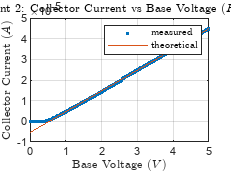


plot(Vin_100k, Ic_100k, '.');
hold on;
plot(Vin_100k, Ir_theoretical_100k);
title("Experiment 2: Collector Current vs Base Voltage ($R=100k\Omega$)", "Interpreter", "latex");
xlabel("Base Voltage ($V$)", "Interpreter", "latex");
ylabel("Collector Current ($A$)", "Interpreter", "latex");
ylim([-1*10^-5 5*10^-5])
xlim([0 5]);
legend(...
    "measured",...
    "theoretical",...
    "Interpreter", "latex")
grid on;
hold off;

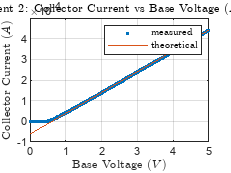

plot(Vin_10k, Ic_10k, '.');
hold on;
plot(Vin_10k, Ir_theoretical_10k);
title("Experiment 2: Collector Current vs Base Voltage ($R=10k\Omega$)", "Interpreter", "latex");
xlabel("Base Voltage ($V$)", "Interpreter", "latex");
ylabel("Collector Current ($A$)", "Interpreter", "latex");
ylim([-1*10^-4 5*10^-4])
xlim([0 5]);
legend(...
    "measured",...
    "theoretical",...
    "Interpreter", "latex")
grid on;
hold off;

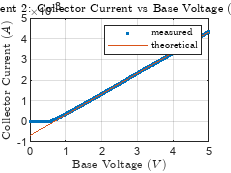

plot(Vin_1k, Ic_1k, '.');
hold on;
plot(Vin_1k, Ir_theoretical_1k);
title("Experiment 2: Collector Current vs Base Voltage ($R=1k\Omega$)", "Interpreter", "latex");
xlabel("Base Voltage ($V$)", "Interpreter", "latex");
ylabel("Collector Current ($A$)", "Interpreter", "latex");
ylim([-1*10^-3 5*10^-3])
xlim([0 5]);
legend(...
    "measured",...
    "theoretical",...
    "Interpreter", "latex")
grid on;
hold off;

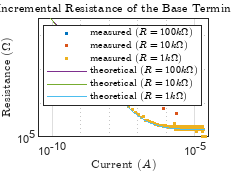


loglog(Ib_100k(2:end), Rb_100k, '.');
hold on;
loglog(Ib_10k(2:end), Rb_10k, '.');
loglog(Ib_1k(2:end), Rb_1k, '.');
loglog(Ib_100k, Rb_theoretical_100k);
loglog(Ib_10k, Rb_theoretical_10k);
loglog(Ib_1k, Rb_theoretical_1k);
title("Experiment 2: Incremental Resistance of the Base Terminal vs Base Current", "Interpreter", "latex");
xlabel("Current ($A$)", "Interpreter", "latex");
ylabel("Resistance ($\Omega$)", "Interpreter", "latex");
ylim([10^5 10^8.5])
xlim([10^-10.5 10^-4.5]);
legend(...
    "measured ($R=100k\Omega$)",...
    "measured ($R=10k\Omega$)",...
    "measured ($R=1k\Omega$)",...
    "theoretical ($R=100k\Omega$)",...
    "theoretical ($R=10k\Omega$)",...
    "theoretical ($R=1k\Omega$)",...
    "Interpreter", "latex")
grid on;
hold off;

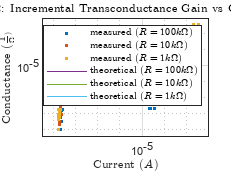


loglog(Ic_100k(2:end), Gm_100k, '.');
hold on;
loglog(Ic_10k(2:end), Gm_10k, '.');
loglog(Ic_1k(2:end), Gm_1k, '.');
loglog(Ic_100k, Gm_theoretical_100k);
loglog(Ic_10k, Gm_theoretical_10k);
loglog(Ic_1k, Gm_theoretical_1k);
title("Experiment 2: Incremental Transconductance Gain vs Collector Current", "Interpreter", "latex");
xlabel("Current ($A$)", "Interpreter", "latex");
ylabel("Conductance ($\frac{1}{\Omega}$)", "Interpreter", "latex");
ylim([10^-9.5 10^-2]);
xlim([10^-9.5 10^-2]);
legend(...
    "measured ($R=100k\Omega$)",...
    "measured ($R=10k\Omega$)",...
    "measured ($R=1k\Omega$)",...
    "theoretical ($R=100k\Omega$)",...
    "theoretical ($R=10k\Omega$)",...
    "theoretical ($R=1k\Omega$)",...
    "Interpreter", "latex")
grid on;
hold off;